# ECE 101 - Structures and Relational Operators

Michael Dekoski

5-2-23

clc
clear

## Relational Operator

vect1 = [12 354 32 -4];
vect2 = [-2 100 50 0];
vect3 = vect1 > vect2

vect3 = 1×4 logical array
   1   1   0   0


## IF/ELSEIF/ELSE/END Structure

yesVar = true;
noVar = false;

if yesVar
    disp('Yes was true')
elseif noVar
    disp('No was true')
else
    disp('Yes was not true, No was not true')
end

Yes was true


## SWITCH Structure

studentCase = 'QY';

switch studentCase
    case 'AW'
        disp('Andrew')
    case 'BK'
        disp('Bravin')
    case 'MD'
        disp('Michael')
    case 'QW'
        disp('Qian')
    otherwise
        disp('Choose a valid option')
end

Choose a valid option


## FOR/END Loop Structure

lastNum = 10;
startNum = 1;
increment = 1;
S = 0;
iteration = 0;
innerIter = 0;

for k = startNum:increment:lastNum
    for h = 1:10
        S = S + (-1^k*k/2^k);
        innerIter = innerIter + 1;
    end
    iteration = iteration + 1;
end

iteration

iteration = 10

innerIter

innerIter = 100

k

k = 10

S

S = -19.8828

h

h = 10

## WHILE/END Loop Structure

numWhile = 1;

while true
    if numWhile == 4
        numWhile = numWhile * 4;
        continue
    elseif numWhile == 16
        break
    end
    numWhile = numWhile * 2;
end

rate = 0.05; inf = 0.02;

year(1) = 0;
W(1) = 0;
AccBal(1) = 3000000;
nextW = 25000;
nextAccBal = AccBal(1)*(1+rate);
n = 2;

while nextAccBal >= nextW
    year(n) = n-1;
    W(n) = nextW;
    AccBal(n) = nextAccBal-W(n);
    nextAccBal = AccBal(n)*(1+rate);
    nextW = W(n)*(1+inf);
    n=n+1;
end
n

n = 35335

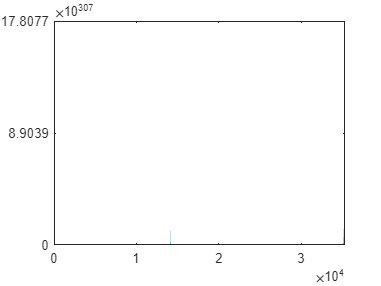

bar(year,[AccBal', W'], 2.0)

## Stopwatch State Machine

stopwatchState = 1;

while true
    if stopwatchState == 1
        % Init main
        disp('Init')

        % Transitional code
        stopwatchState = 2;
    elseif stopwatchState == 0
        % Shutdown
        disp('Shutting Down')
        break
    elseif stopwatchState == 2
        % Waiting
        timeSel = input('Waiting. Input S to Shutdown or Y to start timing: ', 's');
        if timeSel == 'S'
            stopwatchState = 0;
        elseif timeSel == 'Y'
            stopwatchState = 3;
        end
    elseif stopwatchState == 3
        timeStop = input('Timing. Input S to Shutdown or Y to stop timing: ', 's');
        if timeStop == 'S'
            stopwatchState = 0;
        elseif timeStop == 'Y'
            stopwatchState = 2;
        end
    end
end

Init


Shutting Down
